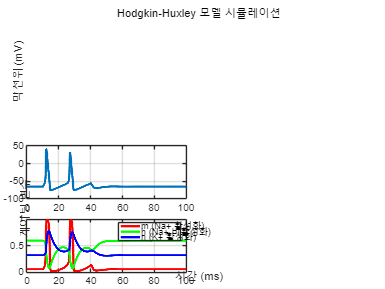

%% Hodgkin-Huxley 신경세포 모델 시뮬레이션
% 이 라이브스크립트는 Hodgkin-Huxley 모델을 시뮬레이션하고 분석합니다.
% 
% 필요한 파일:
% * HHParameters.m
% * HodgkinHuxleyModel.m

%% 1. 모델 초기화 및 기본 시뮬레이션
% 기본 파라미터를 사용하여 시뮬레이션을 실행합니다.

% 모델 인스턴스 생성
model = HodgkinHuxleyModel();

% 기본 시뮬레이션 실행
[time, V, m, h, n] = model.simulate();

% 결과 플롯
model.plot_results(time, V, m, h, n);

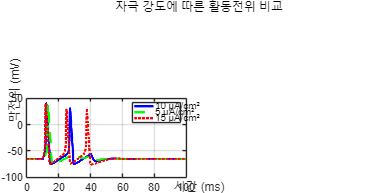


%% 2. 다양한 자극 강도 실험
% 서로 다른 자극 강도에 대한 신경세포의 반응을 비교합니다.

% 자극 강도 정의
I_stim1 = @(t) 5.0 * (t > 10 & t < 40);   % 약한 자극
I_stim2 = @(t) 15.0 * (t > 10 & t < 40);  % 강한 자극

% 시뮬레이션 실행
[time1, V1, m1, h1, n1] = model.simulate(100, 0.01, -65.0, I_stim1);
[time2, V2, m2, h2, n2] = model.simulate(100, 0.01, -65.0, I_stim2);

% 결과 비교 플롯
figure('Position', [100 100 800 400]);
plot(time, V, 'b-', time1, V1, 'g--', time2, V2, 'r:', 'LineWidth', 2);
title('자극 강도에 따른 활동전위 비교');
xlabel('시간 (ms)');
ylabel('막전위 (mV)');
legend('10 μA/cm²', '5 μA/cm²', '15 μA/cm²');
grid on;


%% 3. 결과 분석
% 시뮬레이션 결과의 주요 특징을 분석합니다.

% 활동전위 특성 계산
peak_voltages = [max(V), max(V1), max(V2)];
resting_voltage = V(1);
amplitudes = peak_voltages - resting_voltage;

% 결과 출력
fprintf('활동전위 분석:\n\n');

활동전위 분석:



fprintf('기준 자극 (10 μA/cm²):\n');

기준 자극 (10 μA/cm²):


fprintf('  최대 전위: %.2f mV\n', peak_voltages(1));

  최대 전위: 40.26 mV


fprintf('  진폭: %.2f mV\n\n', amplitudes(1));

  진폭: 105.26 mV




fprintf('약한 자극 (5 μA/cm²):\n');

약한 자극 (5 μA/cm²):


fprintf('  최대 전위: %.2f mV\n', peak_voltages(2));

  최대 전위: 39.05 mV


fprintf('  진폭: %.2f mV\n\n', amplitudes(2));

  진폭: 104.05 mV




fprintf('강한 자극 (15 μA/cm²):\n');

강한 자극 (15 μA/cm²):


fprintf('  최대 전위: %.2f mV\n', peak_voltages(3));

  최대 전위: 40.86 mV


fprintf('  진폭: %.2f mV\n', amplitudes(3));

  진폭: 105.86 mV


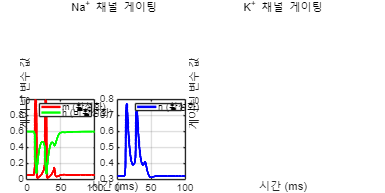


%% 4. 게이팅 변수 동역학 분석
% Na+ 및 K+ 채널의 게이팅 변수들의 시간에 따른 변화를 분석합니다.

figure('Position', [100 100 800 400]);
subplot(1,2,1);
plot(time, m, 'r-', time, h, 'g-', 'LineWidth', 2);
title('Na^+ 채널 게이팅');
xlabel('시간 (ms)');
ylabel('게이팅 변수 값');
legend('m (활성화)', 'h (비활성화)');
grid on;

subplot(1,2,2);
plot(time, n, 'b-', 'LineWidth', 2);
title('K^+ 채널 게이팅');
xlabel('시간 (ms)');
ylabel('게이팅 변수 값');
legend('n (활성화)');
grid on;